# **2D Portal Frame**

This live script is written as a guided walkthrough for a post-processing workflow. It focuses on retrieving, organizing, and visualizing model or response data after an OpenSees analysis. Read the text cells first, then run each code cell in order so that the variables, model state, and recorded results are available for the later sections.

**See the original example in [opsvis](https://opsvis.readthedocs.io/en/latest/ex_2d_portal_frame.html).**

clear

[OpenSeesMatlab]  [EXCEPTION] Polyscope has not been initialized


clc

First, instantiate the class and obtain the OpenSees interface.

opsMAT = OpenSeesMatlab();
ops = opsMAT.opensees;

### Model construction and load application

This section creates the finite-element idealization used by the rest of the example. Check the dimensions, tags, and connectivity here before moving on.

ops.wipe();
ops.model('basic', '-ndm', 2, '-ndf', 3);

colL = 4.0;
girL = 6.0;

Acol  = 2.0e-3;
Agir  = 6.0e-3;
IzCol = 1.6e-5;
IzGir = 5.4e-5;

E = 200.0e9;

ops.node(1, 0.0,   0.0);
ops.node(2, 0.0,   colL);
ops.node(3, girL,  0.0);
ops.node(4, girL,  colL);

ops.fix(1, 1, 1, 1);
ops.fix(3, 1, 1, 0);

ops.geomTransf('Linear', 1);

% columns
ops.element('elasticBeamColumn', 1, 1, 2, Acol, E, IzCol, 1);
ops.element('elasticBeamColumn', 2, 3, 4, Acol, E, IzCol, 1);

% girder
ops.element('elasticBeamColumn', 3, 2, 4, Agir, E, IzGir, 1);

% ops.section('Elastic', 1, E, Agir, IzGir, E/2, 0.75)
% ops.beamIntegration('Lobatto', 1, 1, 5)
% ops.element('forceBeamColumn', 3, 2, 4, 1, 1)

Px =  2.0e3;
Wy = -10.0e3;
Wx =  0.0;
ops.timeSeries('Linear', 1);
ops.pattern('Plain', 1, 1);
ops.load(2, Px, 0.0, 0.0);
ops.eleLoad('-ele', 3, '-type', '-beamUniform', Wy, Wx);

modelData = opsMAT.post.getModelData();

[OpenSeesMatlab] Model summary
  Nodes: 4
  Beam elements: 3


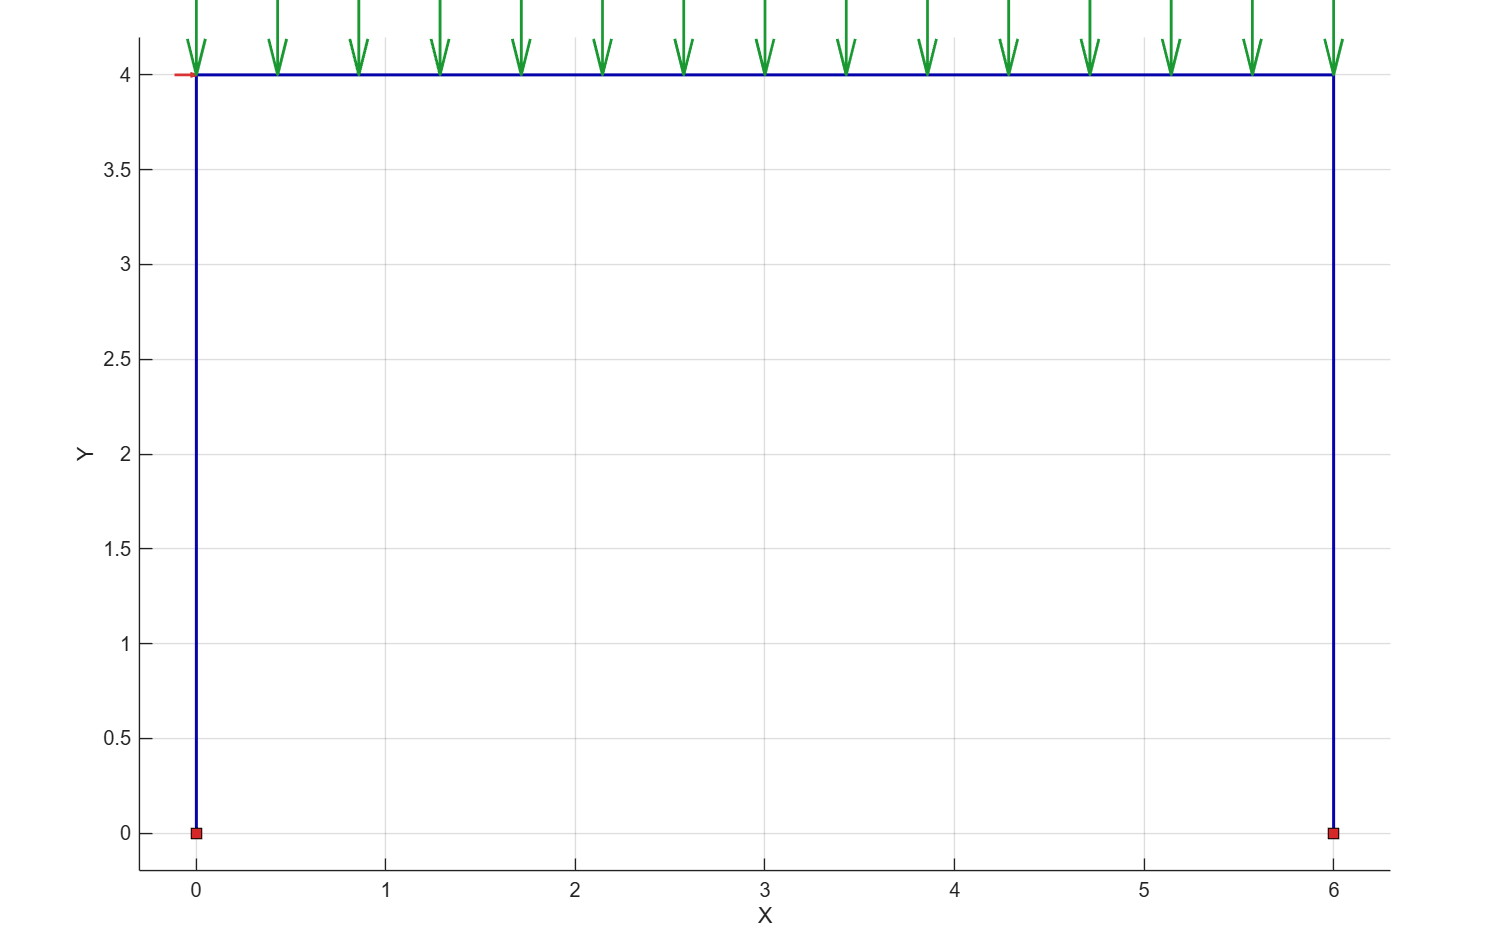

opts = opsMAT.vis.defaultPlotModelOptions;
opts.loads.showNodal = true;
opts.loads.showElement = true;
opts.loads.scale = 1.2;
opsMAT.vis.plotModel(opts=opts);

opsMAT.vis.plotModelGUI();

### Static analysis

This section configures and runs the analysis. The solver, constraints, convergence test, and step size should be read together because they control numerical robustness.

ODB = opsMAT.post.createODB("myODB", interpolateBeamDisp=11);

Output file: .openseesmatlab.output\Responses-myODB.odb\output.h5



Nsteps = 10;
ops.constraints('Transformation');
ops.numberer('RCM');
ops.system('BandGeneral');
ops.test('NormDispIncr', 1.0e-6, 6, 2);
ops.algorithm('Linear');
ops.integrator('LoadControl', 1 / Nsteps);
ops.analysis('Static');

ops.analyze(Nsteps);

### Results visualization

This section collects the quantities of interest from the analysis. The recorded data are used later for plotting, verification, or post-processing.

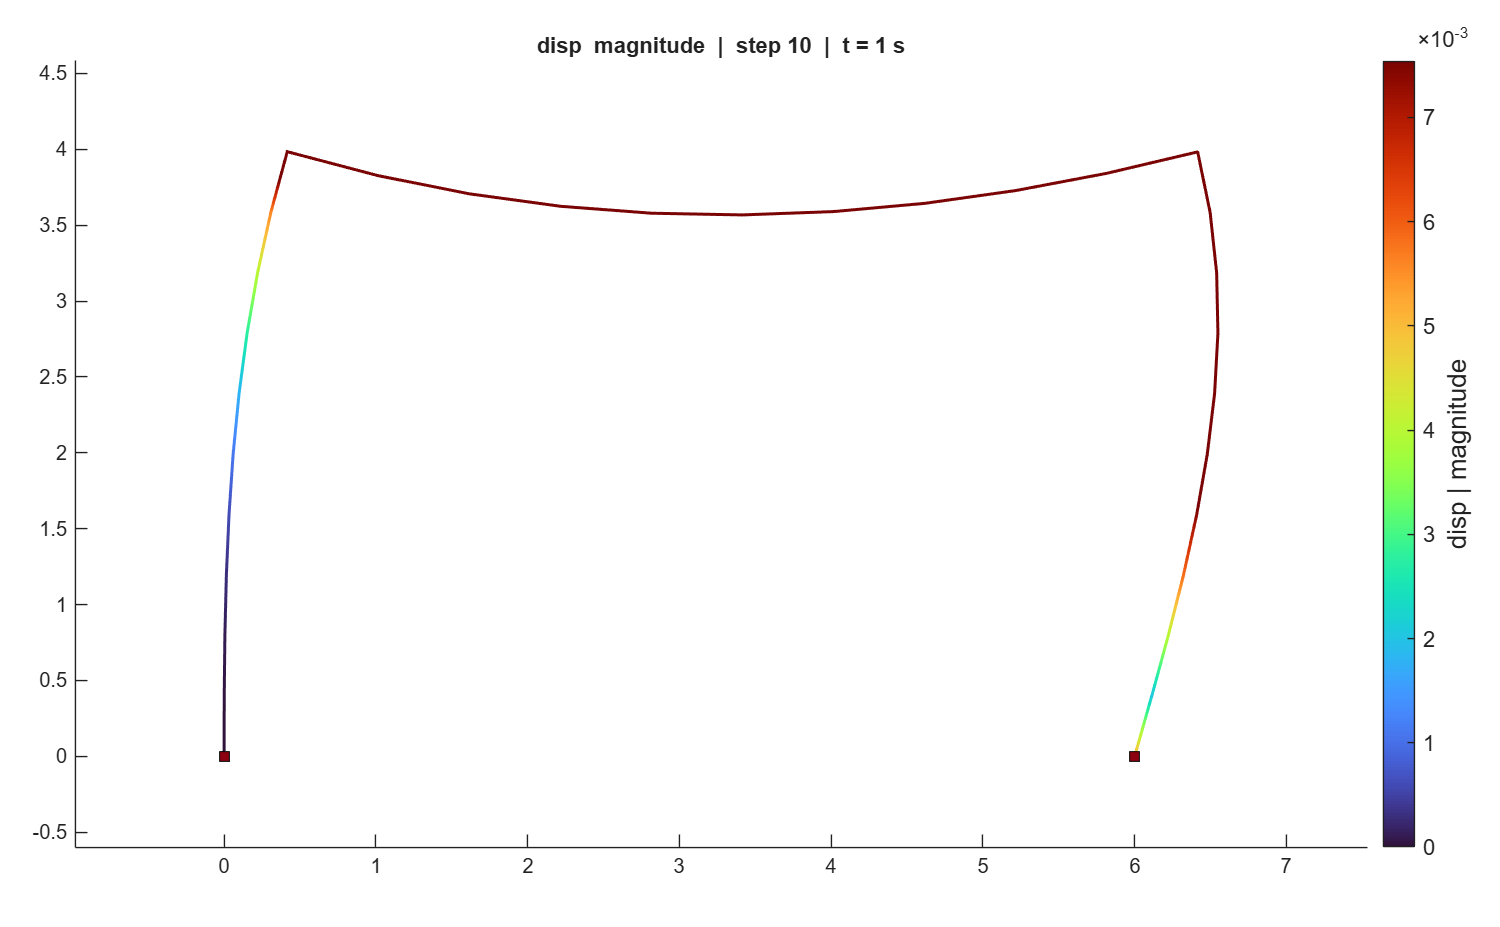

nodeResp = opsMAT.post.getNodalResponse("myODB");

opsMAT.vis.plotNodalResponse(nodeResp, stepIdx="absMax");
grid off

opsMAT.vis.plotNodalResponseGUI(nodeResp);

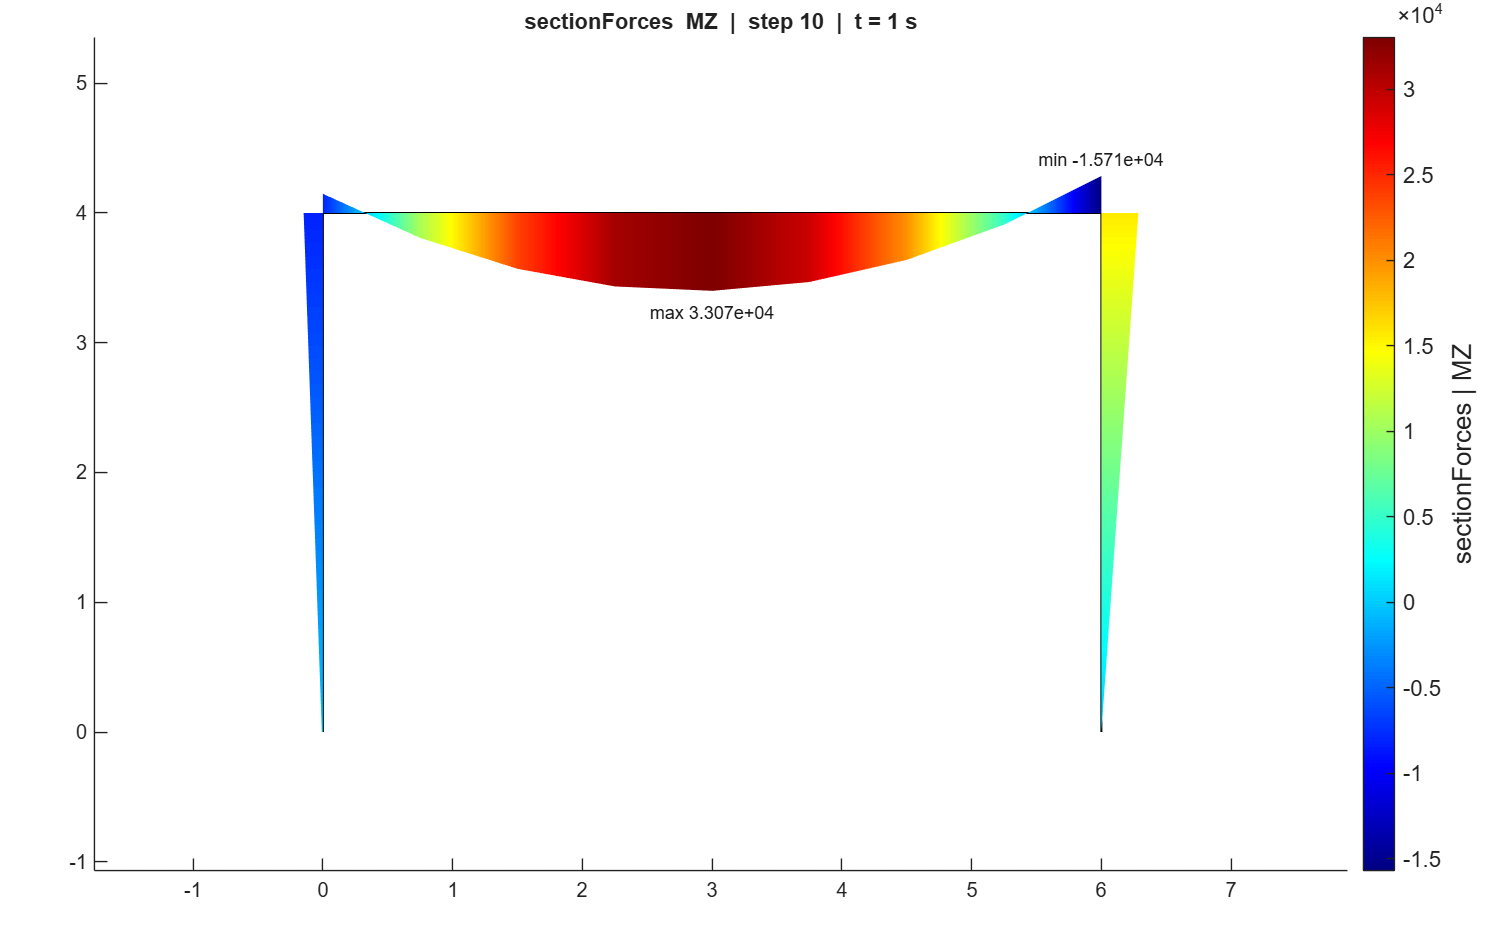

eleResp = opsMAT.post.getElementResponse("myODB", eleType="Frame");

opsMAT.vis.plotFrameResponse(eleResp, ...
    stepIdx="absMax", respType="sectionForces", respComponent="MZ");
grid off

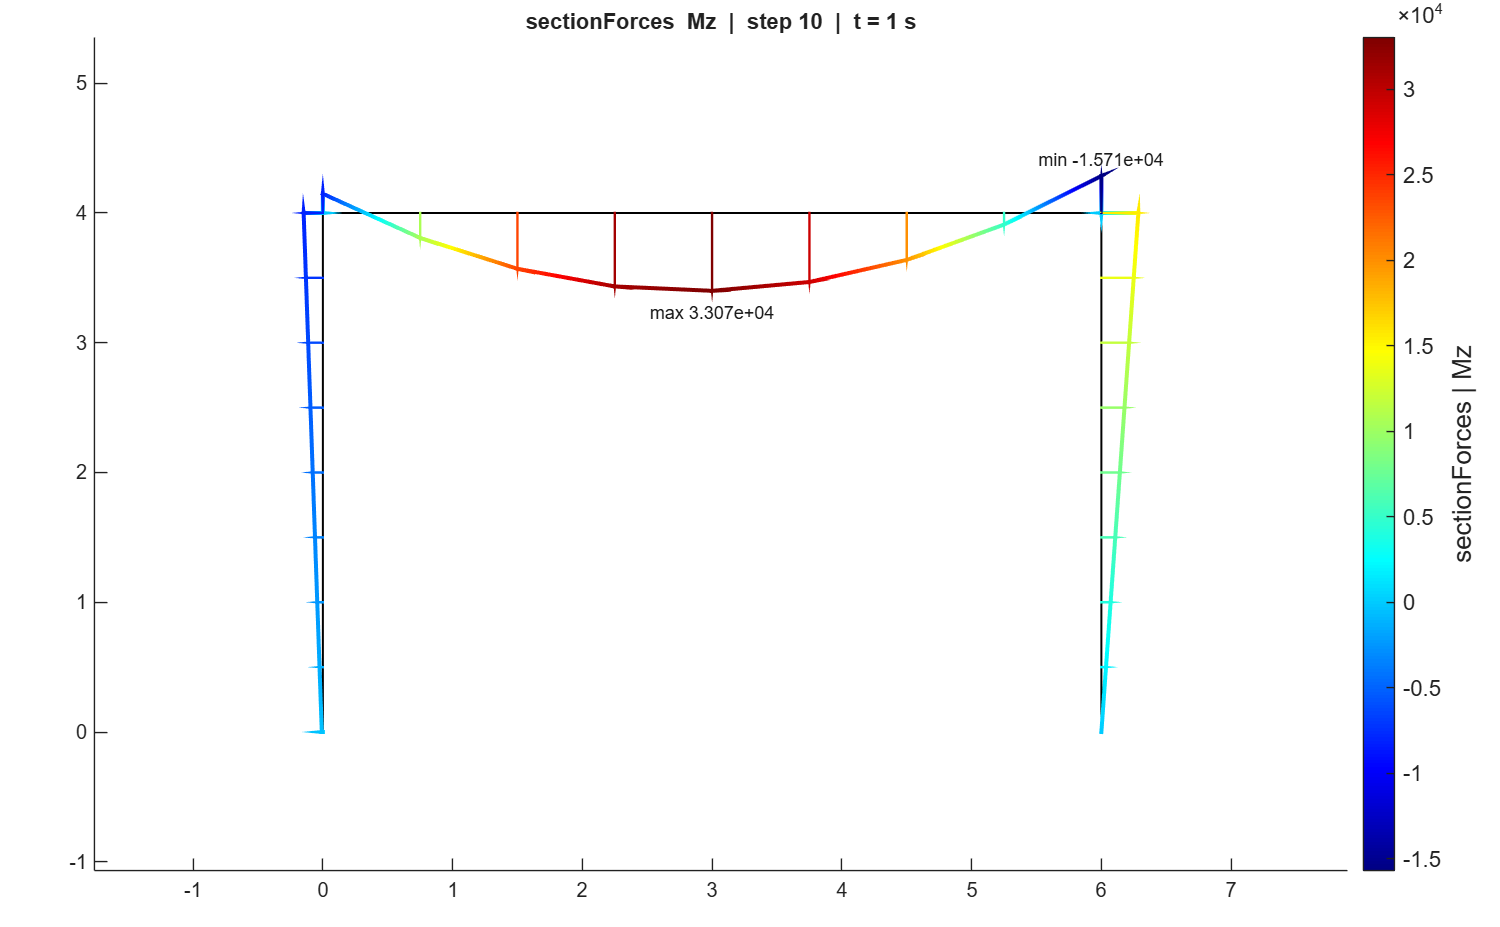

opts = opsMAT.vis.defaultPlotFrameResponseOptions;
opts.style = "wireframe";
opsMAT.vis.plotFrameResponse(eleResp, ...
    stepIdx="absMax", respType="sectionForces", respComponent="Mz",...
    opts=opts);
grid off

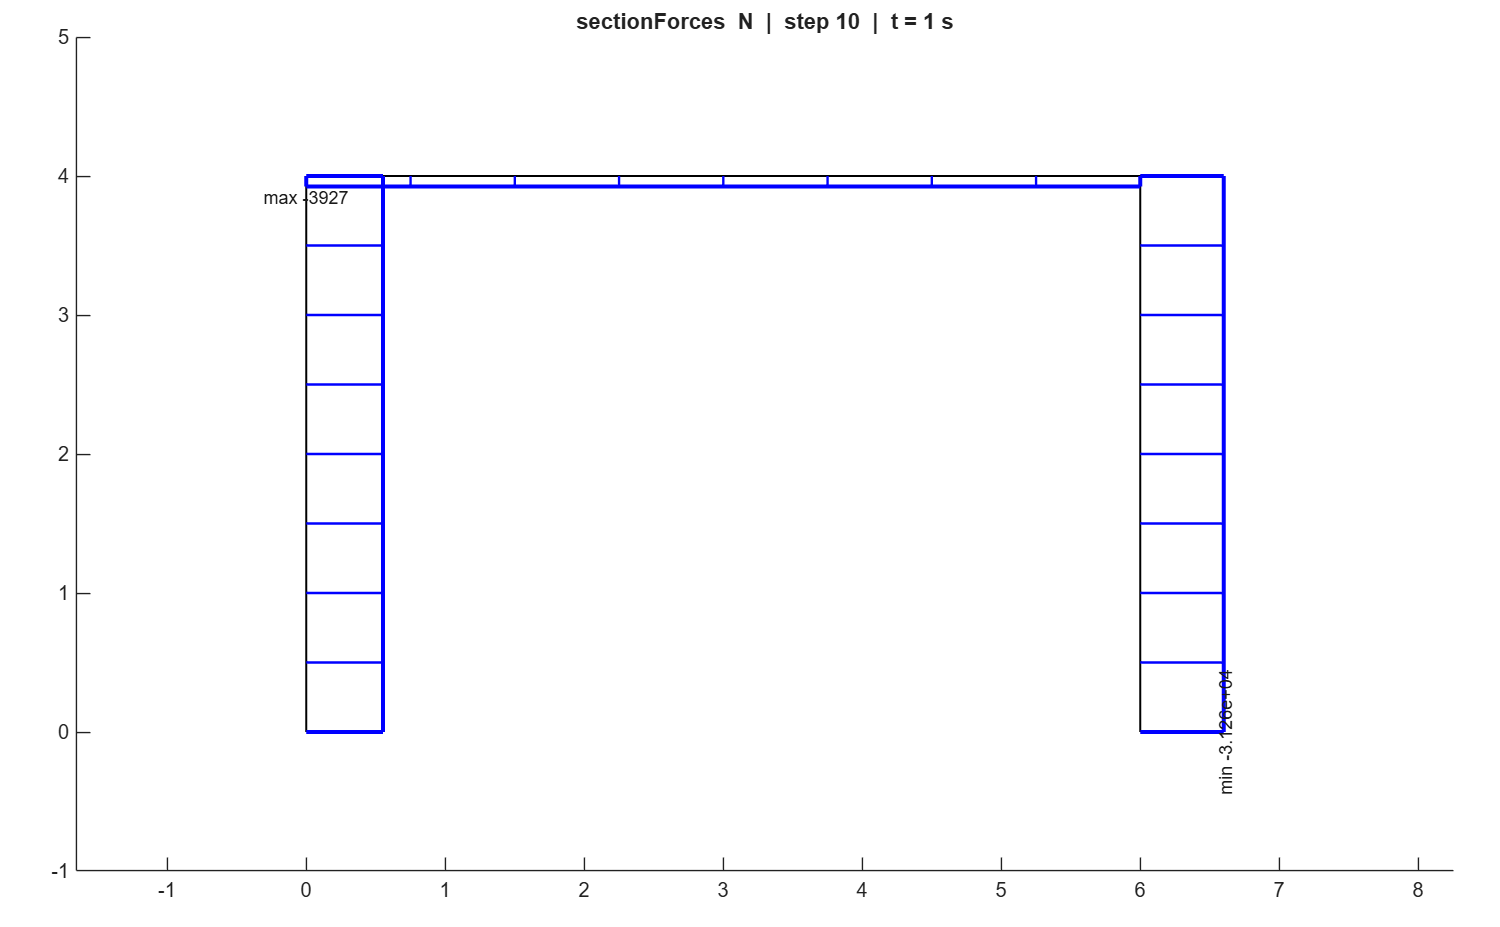

opts.color.useColormap = false;
opsMAT.vis.plotFrameResponse(eleResp, ...
    stepIdx="absMax", respType="sectionForces", respComponent="N",...
    opts=opts);
grid off

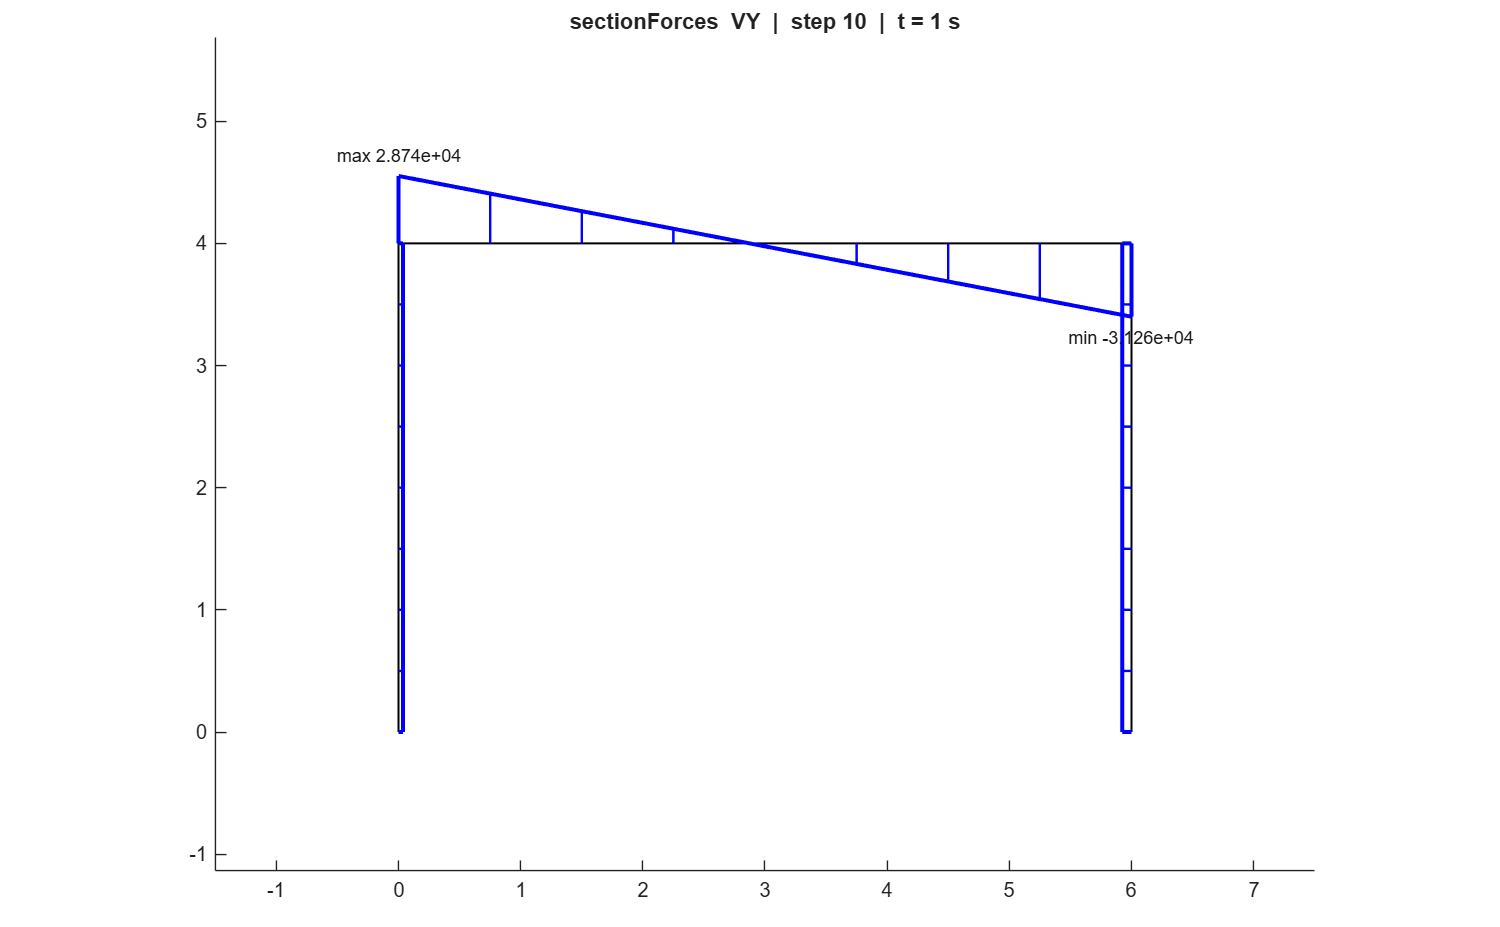

opsMAT.vis.plotFrameResponse(eleResp, ...
    stepIdx="absMax", respType="sectionForces", respComponent="VY",...
    opts=opts);
grid off

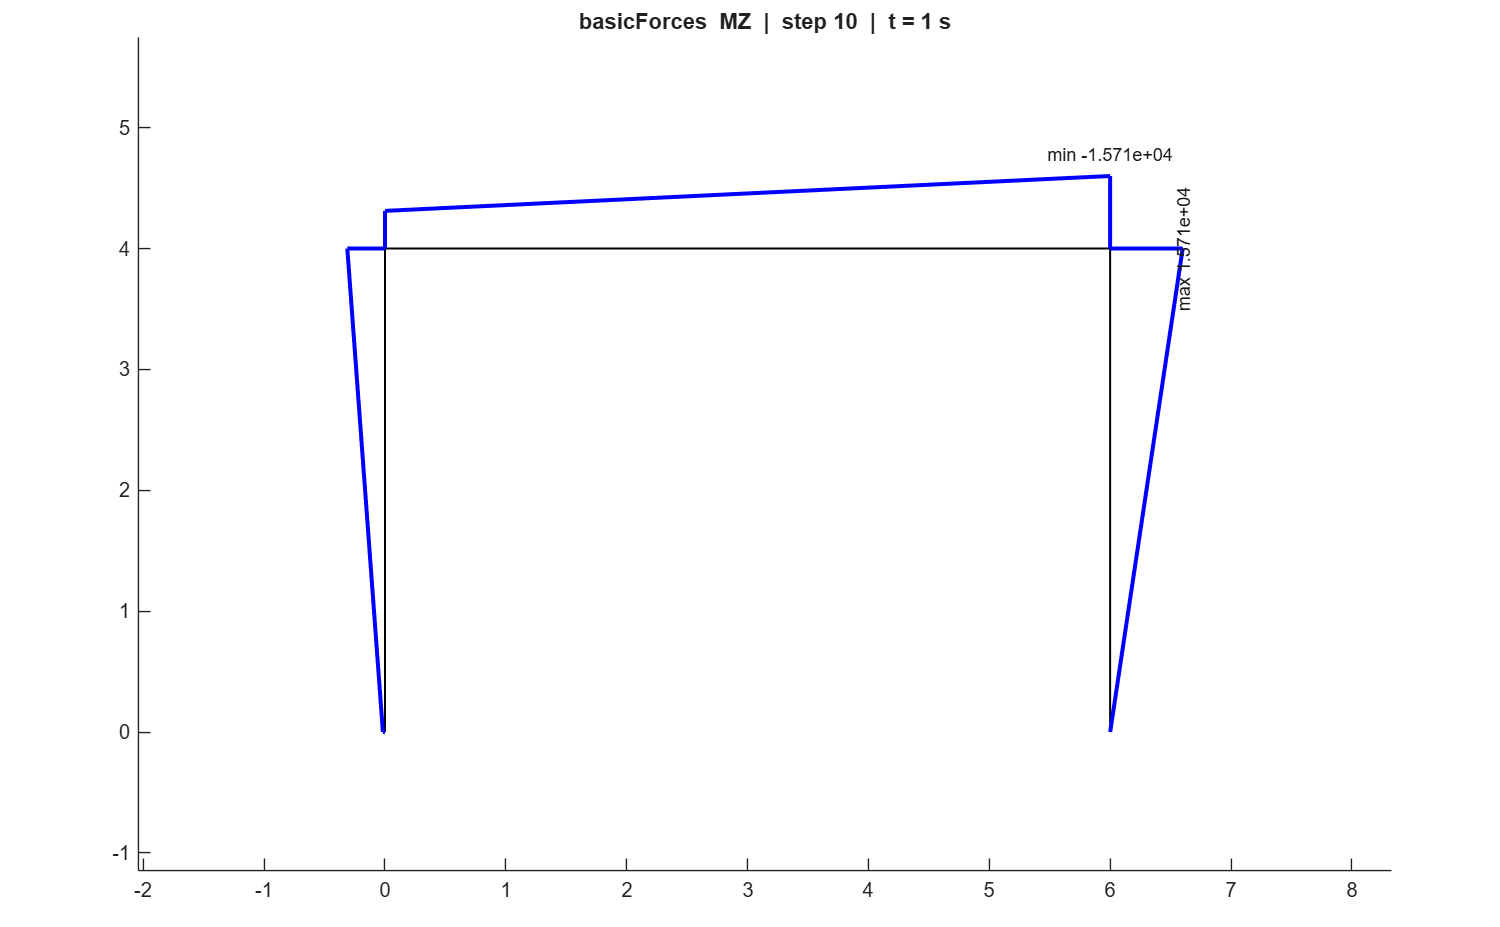

opsMAT.vis.plotFrameResponse(eleResp, ...
    stepIdx="absMax", respType="basicForces", respComponent="MZ",...
    opts=opts);
grid off

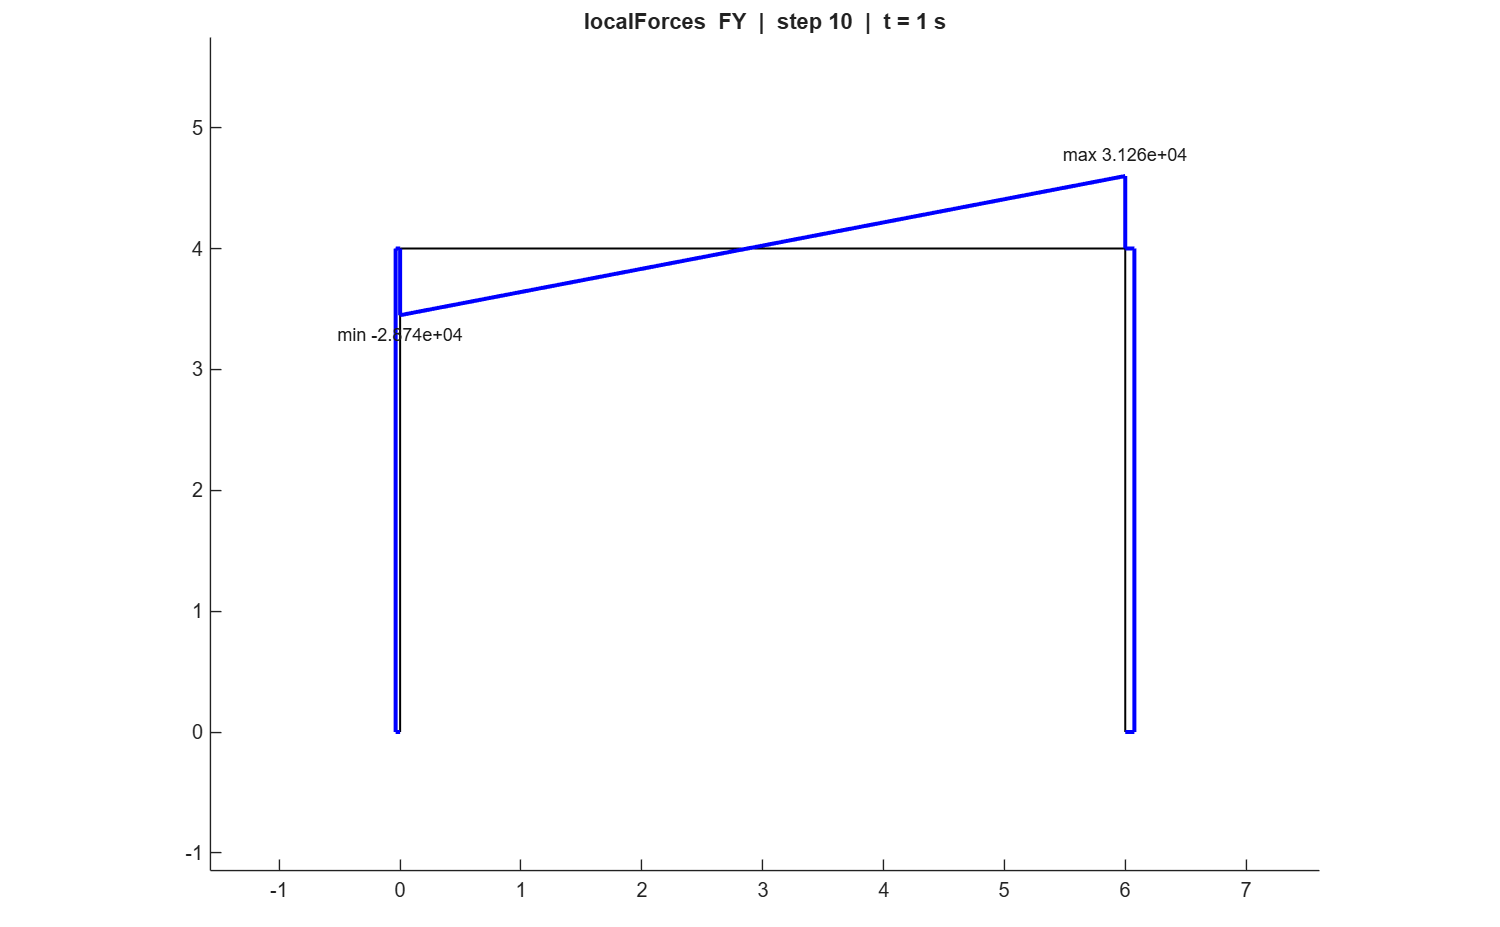

opsMAT.vis.plotFrameResponse(eleResp, ...
    stepIdx="absMax", respType="localForces", respComponent="FY",...
    opts=opts);
grid off

opsMAT.vis.plotFrameResponseGUI(eleResp);

opsMAT.vis.polyscope.plotModel();

[OpenSeesMatlab] Backend: openGL3_glfw -- Loaded openGL version: 3.3.0 NVIDIA 561.09



opsMAT.vis.polyscope.plotNodalResponse(nodeResp);

opsMAT.vis.polyscope.plotFrameResponse(eleResp);

[OpenSeesMatlab] Backend: openGL3_glfw -- Loaded openGL version: 3.3.0 NVIDIA 561.09
